# Attacking Subsystem- Performance Evaluation for spoofing target accuracy

## Initialize the Evaluation Script

clear;
kristen_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
david_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
 file_path = "20MHz.json";
% file_path = "100MHz.json";
% file_path = "1GHz.json";
% file_path = "4GHz.json";

config_path = david_path + file_path;

### Generate Test Ranges and Velocities

valid_ranges = [50,100];
valid_velocities = [-25,25];
num_cases = 200;

[ranges,velocities] = characterization_functions.initialize_attack_subsystem_test_cases(num_cases, ...
                valid_ranges, ...
                valid_velocities);



### Test Ranges

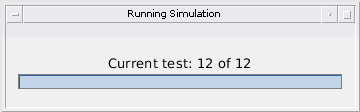

frames_to_compute = 10;
attack_start_frame = 7;
num_attack_frames = frames_to_compute - attack_start_frame;

ranges_to_test = 45:5:100;

num_test_cases = size(ranges_to_test,2);
velocities_to_test = zeros(num_test_cases,1);

%variables to store results
actual_ranges = [];
actual_velocities = [];
estimated_ranges = [];
estimated_velocities = [];

current_test_case = 1;
status = sprintf("Current test: %d of %d",1, num_test_cases);
                progress_bar = waitbar(0,status,"Name","Running Simulation");

for current_test_case = 1:num_test_cases

    status = sprintf("Current test: %d of %d",current_test_case, num_test_cases);
                        waitbar(current_test_case/num_test_cases,progress_bar,status);

    %determine actual ranges
    run_actual_ranges = ranges_to_test(current_test_case) * ones(num_attack_frames + 1,1);
    run_actual_velocities = velocities_to_test(current_test_case) * ones(num_attack_frames + 1,1);
    
    %ru simulation
    [run_estimated_ranges,run_estimated_velocities] = ...
        compute_sensed_targets(config_path,ranges_to_test(current_test_case)...
        ,velocities_to_test(current_test_case),frames_to_compute,attack_start_frame);
    
    %save values
    actual_ranges = [actual_ranges;run_actual_ranges];
    actual_velocities = [actual_velocities; run_actual_velocities];
    estimated_ranges = [estimated_ranges;run_estimated_ranges];
    estimated_velocities = [estimated_velocities; run_estimated_velocities];

end

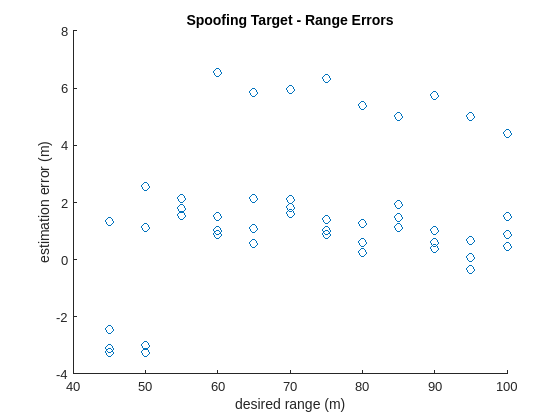

%plot results
range_errors = actual_ranges - estimated_ranges;

clf;
scatter(actual_ranges,range_errors)
title("Spoofing Target - Range Errors")
xlabel("desired range (m)")
ylabel("estimation error (m)")

mean_range_error = mean(range_errors);

var_range_error = var(range_errors);

fprintf("Mean Range Error: %f m",mean_range_error);

Mean Range Error: 1.567480 m

fprintf("Range Error Varriance: %f m",var_range_error);

Range Error Varriance: 5.819311 m

### Test Velocities

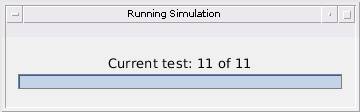

frames_to_compute = 10;
attack_start_frame = 7;
num_attack_frames = frames_to_compute - attack_start_frame;

velocities_to_test = -25:5:25;

num_test_cases = size(velocities_to_test,2);
ranges_to_test = 75 * ones(num_test_cases,1);

%variables to store results
actual_ranges = [];
actual_velocities = [];
estimated_ranges = [];
estimated_velocities = [];

current_test_case = 1;
status = sprintf("Current test: %d of %d",1, num_test_cases);
                progress_bar = waitbar(0,status,"Name","Running Simulation");

for current_test_case = 1:num_test_cases

    status = sprintf("Current test: %d of %d",current_test_case, num_test_cases);
                        waitbar(current_test_case/num_test_cases,progress_bar,status);

    %determine actual ranges
    run_actual_ranges = ranges_to_test(current_test_case) * ones(num_attack_frames + 1,1);
    run_actual_velocities = velocities_to_test(current_test_case) * ones(num_attack_frames + 1,1);
    
    %ru simulation
    [run_estimated_ranges,run_estimated_velocities] = ...
        compute_sensed_targets(config_path,ranges_to_test(current_test_case)...
        ,velocities_to_test(current_test_case),frames_to_compute,attack_start_frame);
    
    %save values
    actual_ranges = [actual_ranges;run_actual_ranges];
    actual_velocities = [actual_velocities; run_actual_velocities];
    estimated_ranges = [estimated_ranges;run_estimated_ranges];
    estimated_velocities = [estimated_velocities; run_estimated_velocities];

end

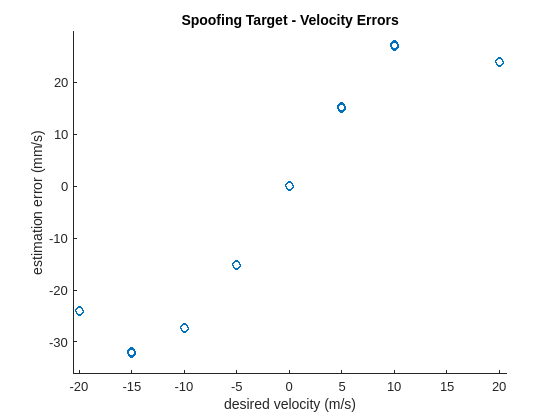

%plot results
velocity_errors = actual_velocities - estimated_velocities;
velocity_errors_mm_s = velocity_errors * 1e3;

clf;
scatter(actual_velocities,velocity_errors_mm_s)
title("Spoofing Target - Velocity Errors")
xlabel("desired velocity (m/s)")
ylabel("estimation error (mm/s)")

mean_velocity_error = mean(velocity_errors_mm_s);

var_velocity_errors = var(velocity_errors_mm_s);

fprintf("Mean Velocity Error: %f mm/s",mean_velocity_error);

Mean Velocity Error: -0.006272 mm/s

fprintf("Velocity Error Variance: %f mm/s",var_velocity_errors);

Velocity Error Variance: 485.888655 mm/s